clearvars; close all; clc;

# Multi entry horn response

2025-05-19, JVsound, J.G. Vermond

eglf			= 60;
egmf			= 35;
val				= mehresponsebuild(eglf,egmf);

## LF

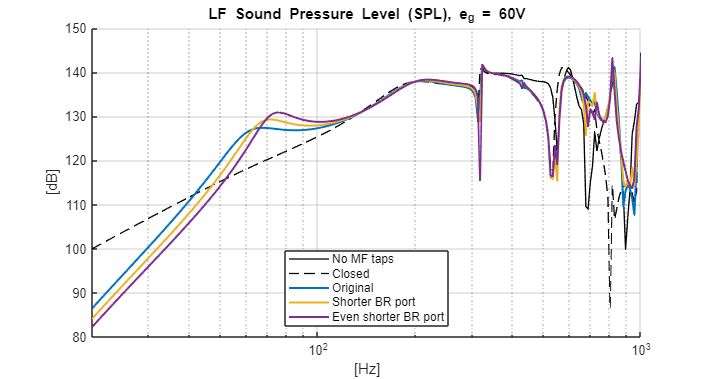

fig1				= figure;
fig1.Position		= [50 50 935 500];
fig1.Color			= "w";
ax1					= axes(fig1); hold on; grid on;
ax1.FontSize		= 10;
ax1.XScale			= "log";
ax1.XLim			= [val.lf.f(1) val.lf.f(end)];
ax1.XLabel.String	= "[Hz]";
ax1.YLabel.String	= "[dB]";
ax1.Title.String	= ['LF Sound Pressure Level (SPL), e_g = ' num2str(eglf) 'V'];

plot(ax1,val.lfwt.f,val.lfwt.spl,LineWidth=1,Color="k")
plot(ax1,val.lfcl.f,val.lfcl.spl,LineWidth=1,LineStyle="--",Color="k")
ax1.ColorOrderIndex = 1;
plot(ax1,val.lf.f,val.lf.spl,LineWidth=1.5)
ax1.ColorOrderIndex = 3;
plot(ax1,val.lfbrm.f,val.lfbrm.spl,LineWidth=1.5);
plot(ax1,val.lfbrm2.f,val.lfbrm2.spl,LineWidth=1.5);

leg1			= legend(ax1,"No MF taps","Closed","Original","Shorter BR port","Even shorter BR port");
leg1.Location	= "south";

## MF

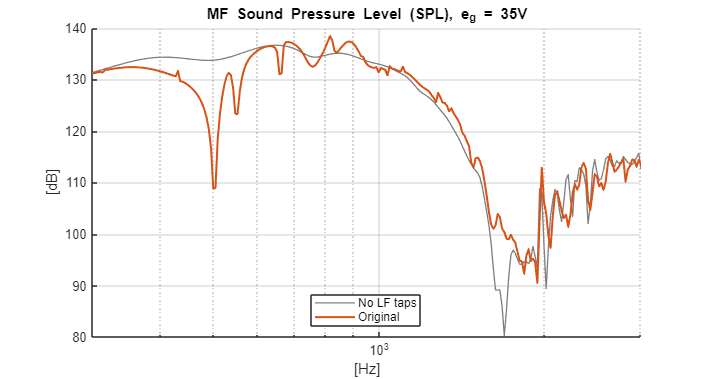

fig2				= figure;
fig2.Position		= [50 50 935 500];
fig2.Color			= "w";
ax2					= axes(fig2); hold on; grid on;
ax2.FontSize		= 10;
ax2.XScale			= "log";
ax2.XLim			= [val.mf.f(1) val.mf.f(end)];
ax2.XLabel.String	= "[Hz]";
ax2.YLabel.String	= "[dB]";
ax2.Title.String	= ['MF Sound Pressure Level (SPL), e_g = ' num2str(egmf) 'V'];

plot(ax2,val.mfwt.f,val.mfwt.spl,LineWidth=1,Color=[.5 .5 .5]);
ax2.ColorOrderIndex = 2;
plot(ax2,val.mf.f,val.mf.spl,LineWidth=1.5)

leg2			= legend(ax2,"No LF taps","Original");
leg2.Location	= "south";

## LF + MF

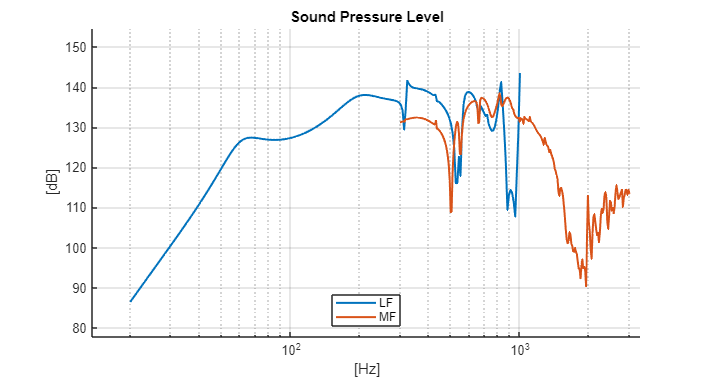

fig3				= figure;
fig3.Position		= [50 50 935 500];
fig3.Color			= "w";
ax3					= axes(fig3); hold on; grid on;
ax3.FontSize		= 10;
ax3.XScale			= "log";
ax3.XLim			= [val.lf.f(1) val.mf.f(end)];
ax3.XLabel.String	= "[Hz]";
ax3.YLabel.String	= "[dB]";
ax3.Title.String	= "Sound Pressure Level";

plot(ax3,val.lf.f,val.lf.spl,LineWidth=1.5);
plot(ax3,val.mf.f,val.mf.spl,LineWidth=1.5);

leg3			= legend(ax3,"LF","MF");
leg3.Location	= "south";

Excursion

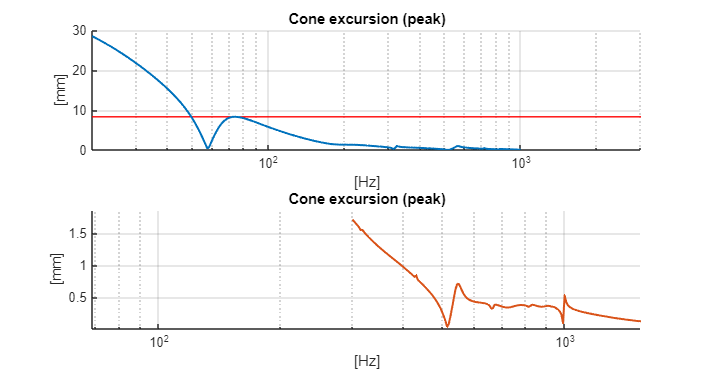

fig4			= figure;
fig4.Position	= [50 50 935 500];
fig4.Color		= "w";
ax41			= subplot(2,1,1,parent=fig4); hold on; grid on;
ax41.FontSize	= 10;
ax41.XScale		= "log";
ax41.XLim		= [val.lf.f(1) val.mf.f(end)];
ax41.XLabel.String	= "[Hz]";
ax41.YLabel.String	= "[mm]";
ax41.Title.String	= "Cone excursion (peak)";
ax42			= subplot(2,1,2,parent=fig4); hold on; grid on;
ax42.FontSize	= 10;
ax42.XScale		= "log";
ax42.XLim		= [val.lf.f(1) val.mf.f(end)];
ax42.XLabel.String	= "[Hz]";
ax42.YLabel.String	= "[mm]";
ax42.Title.String	= "Cone excursion (peak)";

plot(ax41,ax41.XLim,repmat(val.lf.sp.xmax*1e3,1,2),"r")
ax41.ColorOrderIndex = 1;
plot(ax41,val.lf.f,abs(val.lf.sim2port.x)*sqrt(2)*1e3,LineWidth=1.5)

plot(ax42,ax42.XLim,repmat(val.mf.sp.xmax*1e3,1,2),"r")
ax42.ColorOrderIndex = 2;
plot(ax42,val.mf.f,abs(val.mf.sim2port.x)*sqrt(2)*1e3,LineWidth=1.5)

## HF